clear; close; clc;
t=0:1:5;
popu=[5.2,4.5,2.7,2.5,2.1,1.9];
A=1;B=1;%待求的两个参量
k=0;%迭代次数
eps=1e-5;%允许的误差
r=A*exp(B*t)-popu;%误差
r1=zeros(size(r));%记录上一次误差
dA=1e-5;
dB=1e-5;
alpha=10;%LM法的下降因子
while(1)
    if(sum(abs(r1-r))<eps)||(k>300)
        A,B,k
        break
    else
        pA=(((A+dA)*exp(B*t))-(A-dA)*exp(B*t))/(2*dA);%关于A的偏导数，利用数值微分思想
        pB=(A*exp((B+dB)*t)-A*exp((B-dB)*t))/(2*dB);%关于B的偏导数
         H = [sum(pA.*pA) sum(pA.*pB)    
             sum(pA.*pB) sum(pB.*pB)];  %黑塞矩阵，此处黑塞矩阵没有考虑二阶信息
        df = [sum(r.*pA)  
              sum(r.*pB)];                 	%梯度
          
        k = k + 1;
        delta = (inv(H + alpha*eye(2))) * df;	%变化量
        A = A - delta(1);                   %更新待求参数A
        B = B - delta(2);                   %更新待求参数B
        
        r1 = r;                             %记录上一次误差
        r = A*exp(B*t) - popu;              %更新误差
    end
end

A = 5.2140

B = -0.2343

k = 95

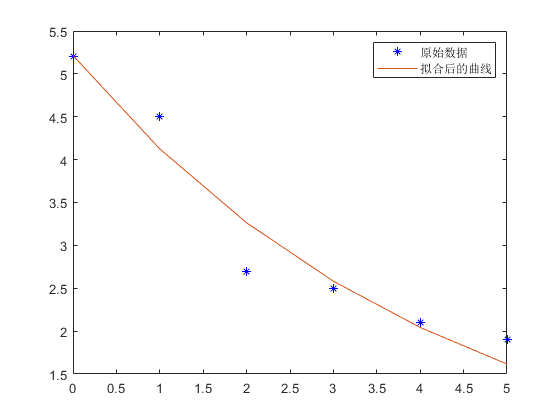

plot(t,popu,'b*',t,A*exp(B*t)),
legend('原始数据','拟合后的曲线')